请选择参数输入方式：
1. 使用默认参数
2. 自定义输入参数


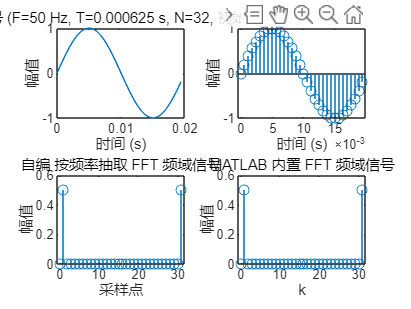

按频率抽取 FFT 与 MATLAB FFT 最大差异: 5.463e-15


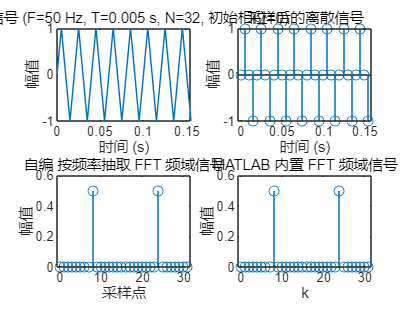

按频率抽取 FFT 与 MATLAB FFT 最大差异: 9.7972e-16


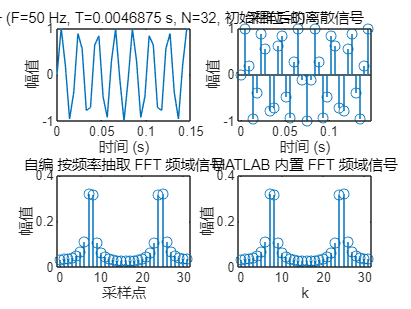

按频率抽取 FFT 与 MATLAB FFT 最大差异: 2.5121e-15


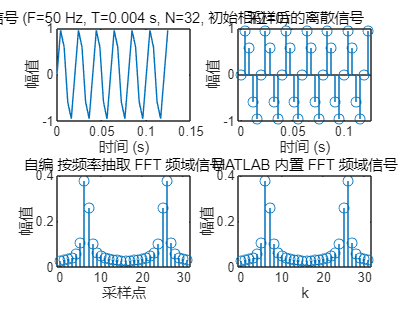

按频率抽取 FFT 与 MATLAB FFT 最大差异: 2.5121e-15


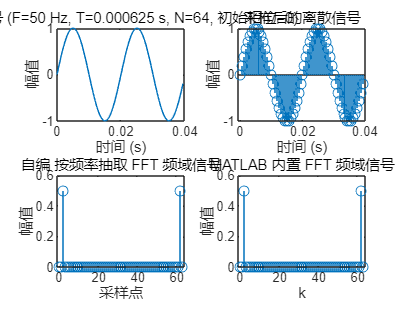

按频率抽取 FFT 与 MATLAB FFT 最大差异: 1.1416e-14


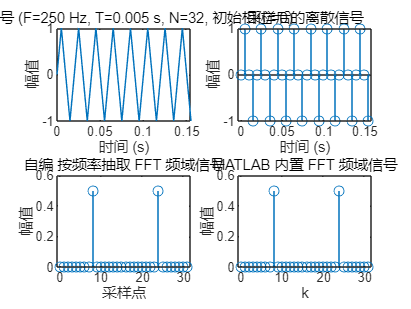

按频率抽取 FFT 与 MATLAB FFT 最大差异: 9.7972e-16


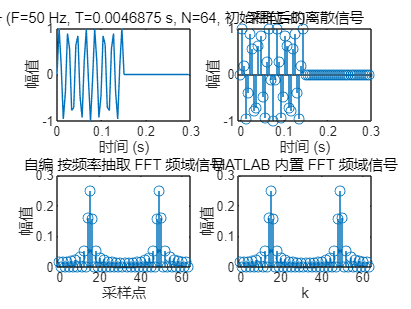

按频率抽取 FFT 与 MATLAB FFT 最大差异: 5.8344e-15


% 基-2按频率抽取的FFT算法
function X = FFT_freq_extract(x)
    N = length(x);
    X = bit_reverse_order(x);  % 二进制反转顺序排列
    stages = log2(N);  % FFT 需要的阶段数

    % 基-2按频率抽取计算过程
    for s = 1:stages%蝶形运算
        m = 2^s;
        W_m = exp(-2i*pi*(0:m/2-1)/m);  % 旋转因子
        for k = 0:(N/m - 1)%阶段处理
            for j = 1:m/2%合并操作
                t = W_m(j) * X(k*m + j + m/2);
                u = X(k*m + j);
                X(k*m + j) = u + t;
                X(k*m + j + m/2) = u - t;
            end
        end
    end
end

% 二进制反转顺序排列
function X = bit_reverse_order(x)
    N = length(x);
    X = zeros(1, N);
    num_bits = log2(N);
    
    for n = 0:N-1
        reversed_n = bit_reverse(n, num_bits);
        X(reversed_n + 1) = x(n + 1);  % MATLAB 索引从 1 开始
    end
end

% 二进制反转
function r = bit_reverse(n, num_bits)
    r = 0;
    for i = 0:num_bits-1
        r = bitor(r, bitshift(bitand(n, 1), num_bits - 1 - i));
        n = bitshift(n, -1);
    end
end

% 比较按频率抽取 FFT 和 MATLAB 内置 FFT 结果
function compare_fft_freq_extract(F, T, N, m, zero_padding)
    % 生成信号，带有初始相位m
    t = (0:N-1) * T;
    x = sin(2*pi*F*t + m);
    
    % 补零选项
    if zero_padding
        x = [x, zeros(1, N)]; % 补零至2*N样点
        N = 2 * N; % 更新样点数
    end
    
    % 自编按频率抽取的 FFT
    X_custom_freq = FFT_freq_extract(x);
    
    % MATLAB 内置 FFT
    X_builtin = fft(x);
    
    % 绘制时域图
    figure;
    subplot(2,2,1);
    plot((0:N-1)*T, x);
    title(['时域信号 (F=', num2str(F), ' Hz, T=', num2str(T), ' s, N=', num2str(N), ', 初始相位=', num2str(m), ')']);
    xlabel('时间 (s)');
    ylabel('幅值');
    
    subplot(2,2,2);
    stem((0:N-1)*T, x);
    title('采样后的离散信号');
    xlabel('时间 (s)');
    ylabel('幅值');
    % 绘制频域比较图
    subplot(2,2,3);
    stem(0:N-1, abs(X_custom_freq)/N);  % 将横坐标修改为采样点索引
    title('自编 按频率抽取 FFT 频域信号');
    xlabel('采样点');
    ylabel('幅值');

    
    subplot(2,2,4);
    stem(0:N-1, abs(X_builtin)/N);
    title('MATLAB 内置 FFT 频域信号');
    xlabel('k');
    ylabel('幅值');

   
    % 比较结果
    diff = max(abs(X_custom_freq - X_builtin));
    disp(['按频率抽取 FFT 与 MATLAB FFT 最大差异: ', num2str(diff)]);
end

% 主函数，添加参数输入选择
function main_fft_freq()
    disp('请选择参数输入方式：');
    disp('1. 使用默认参数');
    disp('2. 自定义输入参数');
    choice = input('输入您的选择 (1 或 2): ');
    
    if choice == 1
        % 使用默认参数
        run_default_tests_time();
    elseif choice == 2
        % 自定义参数输入
        F = input('信号频率F/hz= ');
        N = input('采样点数N= ');
        T = input('采样时间间隔T/s= ');
        m = input('初始相位= ');
        flag = input('是否补零（1为yes/0为no）= ');
        compare_fft_freq_extract(F, T, N, m, flag);
    else
        disp('无效的选择');
    end
end

% 默认参数测试
function run_default_tests_time()
    % a) F=50Hz, N=32, T=0.000625s, 初始相位=0
    compare_fft_freq_extract(50, 0.000625, 32, 0, 0);

    % b) F=50Hz, N=32, T=0.005s, 初始相位=0
    compare_fft_freq_extract(50, 0.005, 32, 0, 0);

    % c) F=50Hz, N=32, T=0.0046875s, 初始相位=0
    compare_fft_freq_extract(50, 0.0046875, 32, 0, 0);

    % d) F=50Hz, N=32, T=0.004s, 初始相位=0
    compare_fft_freq_extract(50, 0.004, 32, 0, 0);

    % e) F=50Hz, N=64, T=0.000625s, 初始相位=0
    compare_fft_freq_extract(50, 0.000625, 64, 0, 0);

    % f) F=250Hz, N=32, T=0.005s, 初始相位=0
    compare_fft_freq_extract(250, 0.005, 32, 0, 0);

    % g) F=50Hz, N=32, T=0.0046875s, 初始相位=0, 补零
    compare_fft_freq_extract(50, 0.0046875, 32, 0, 1);
end

% 运行按时间抽取FFT测试
main_fft_freq();